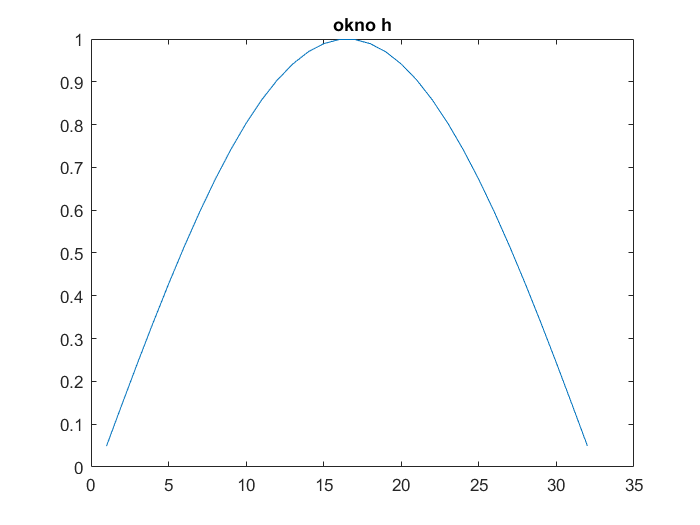

clc; clear all; close all;

[x,fpr] = audioread('DontWorryBeHappy.wav');
x = x(:,1);
N = 32; % długość okna
k = 0:N/2-1;
n = 0:N-1;
ileProbek = floor((length(x)-(N/2))/(N/2));

%okno
h = sin(pi*(n+0.5)/N);
figure;
plot(h);
title('okno h');

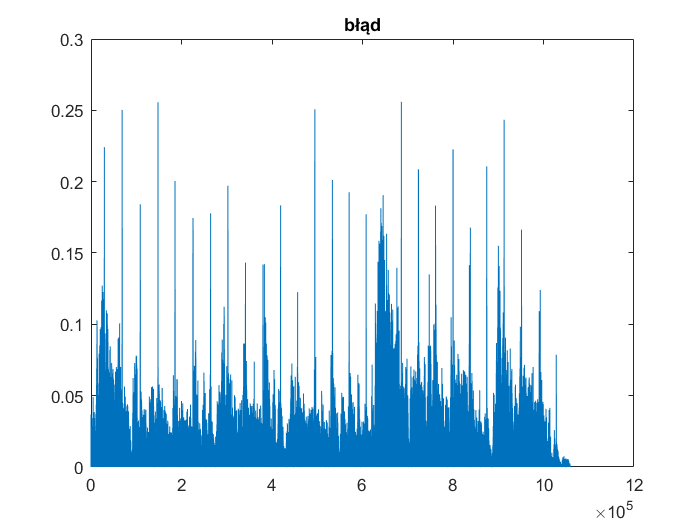


A = sqrt(4/N) * cos((2*pi/N) * (k+0.5)' .* (n+0.5+N/4));
S = A.';    % transpozycja A
Q=2;        % 16 maly blad 
wynik=zeros(length(x),1);

for n = 1:ileProbek
    % analiza
    probka = x(1+(n-1)*(N/2) : N+(n-1)*(N/2));
    x1 = h' .* probka;
    x1 = A * x1;
    %y = round(x1*Q);
    y = kwant(x1,Q);
    
    % synteza
    y = S * y;
    y = h .* y'; 
    y=y';
    wynik(1+(n-1)*(N/2): N+(n-1)*(N/2)) = wynik(1+(n-1)*(N/2): N+(n-1)*(N/2))+y;
end

% 64*10^3 = fpr[Hz]*v;
% v[bit]*fs[kHz] = przepłwność[kbps] 

bits = 64000/fpr; %1.4 -> Q=2

wynik = wynik;
blad = abs(wynik - x);
figure;
plot(blad);
title('błąd');

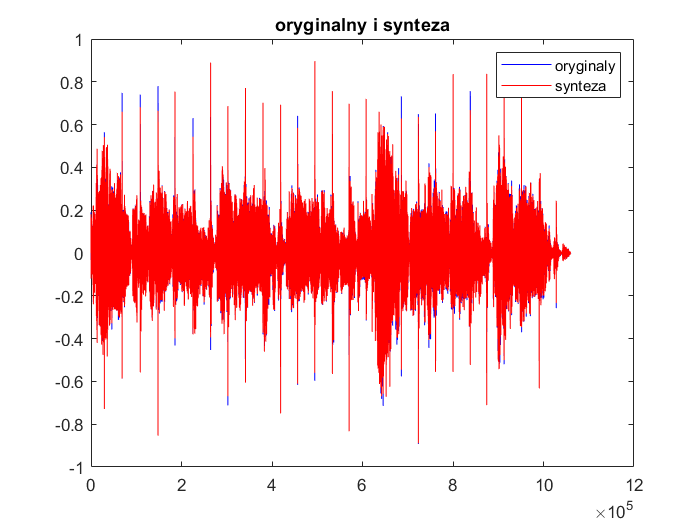


figure;
plot(x,'b');
hold on;
plot(wynik,'r');
legend('oryginaly','synteza');
title("oryginalny i synteza");

%soundsc(wynik,fpr);